# SIM.8 Modeling and Simulation of Ball Dynamics

Develop the provide pseudo code to solve the Ball dynamics iaw the Euler’s method in Lecture

Notes #4. The sampling period is 0.02 seconds. Address the following.

Model Parameters: Identify the parameters of the model that need to be estimated. Get values for

these parameters from the Web. Compare with someone else’s results.

M = 0.0027 kg

Cd = 0.5

p = 1.225 kg/m^3

A = 1.26 x 10^-3 m^2

g = 9.81 m/s^2

T = 0.02 s

M = 0.0027; % mass (kg)
Cd = 0.5; % drag coefficient
p = 1.225; % air density (kg/m^3)
A = 1.26 * 10^-3; % cross sectional area (m^2)
g = 9.81; % acceleration due to gravity (m/s^2)
B = 0.5 * Cd * p * A; % beta constant
T = 0.02; % sampling period (s)

Zero Control Input: This is the free-falling response. The Ball’s initial position is 0.254 meters

and its initial velocity is 0 meters per second. Plot Ball position v. time. Does the model predict

the expected falling motion of the Ball?

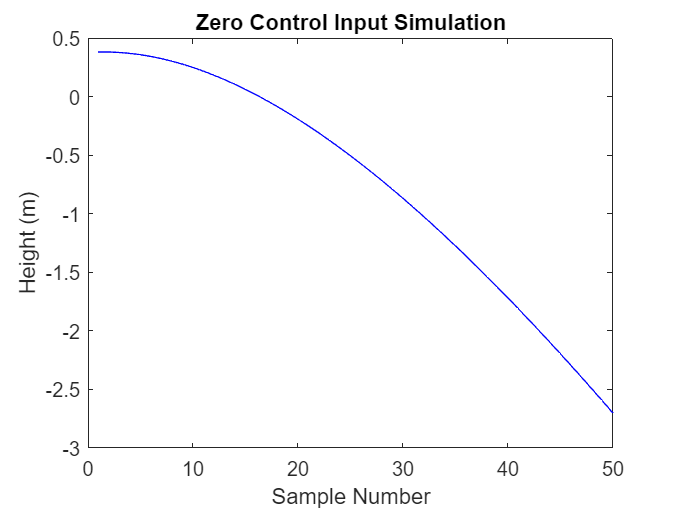

n = 50; % number of samples
x1 = zeros(1,n); % initialize velocity matrix
x2 = zeros(1,n); % initialize position matrix
x1(1) = 0; % start at rest
x2(1) = 0.381; % start at 0.381 m

% loop through number of samples
for i = 1:n-1
    x1(i+1) = x1(i) - g * T - (1/M) * 10 * B * x1(i) * T; % update velocity matrix
    x2(i+1) = x2(i) + x1(i) * T; % update position matrix
end

plot(1:n, x2, 'b') % plot position 
title("Zero Control Input Simulation")
xlabel("Sample Number")
ylabel("Height (m)") 

Relay Control: Same Initial Conditions (ICs).

1--Set the baseline control to equal the weight of the Ball. Set the incremental control to 1% of

the Ball’s weight. Plot Ball position v. time. Does relay control perform as expected?

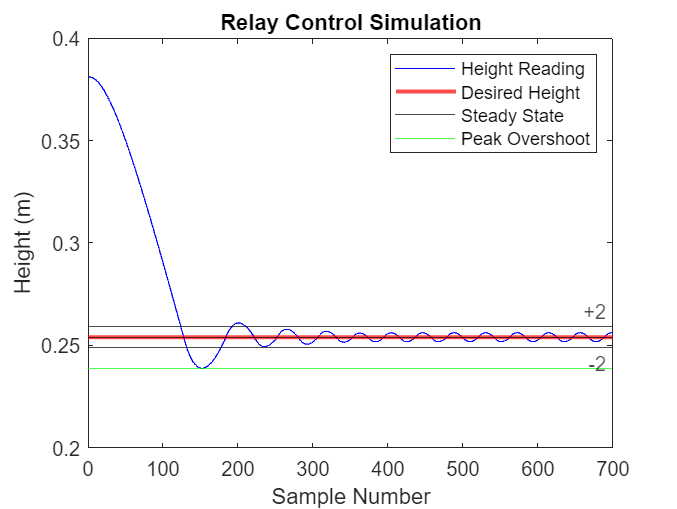

n = 700; % number of samples
x1 = zeros(1,n); % initialize velocity matrix
x2 = zeros(1,n); % initialize position matrix
x1(1) = 0; % start at rest
x2(1) = 0.381; % start at 0.381 m

desired_height = 0.254; 
baseline = M * g; % baseline equal to weight
incremental = 0.01 * M * g; % incremental equal to 1% of weight
u = zeros(1,n-1); % initialize control input matrix

% loop through number of samples
for i = 1:n-1
    error = desired_height - x2(i); % calculate error
    
    % relay control logic
    if error > 0
        u(i) = baseline + incremental; % increase control input if below desired height
    else
        u(i) = baseline - incremental; % decrease control input if above desired height
    end

    x1(i+1) = x1(i) - g * T - (1/M) * 10 * B * x1(i) * T + (1/M) * u(i) * T; % update velocity matrix
    x2(i+1) = x2(i) + x1(i) * T; % update position matrix
end

plot(1:n, x2, 'b') % plot position
ylim([0.2 0.4])
yline(desired_height, "r",'LineWidth', 2) % plot desired height line
ss = mean(x2(400:end)); % calculate steady state error
yline(ss, 'k') % plot steady state
peak = min(x2); % calculate peak overshoot
yline(peak, 'g') % plot peak overshoot line
% calculate and plot + or - 2% steady state 
ss_max = ss * 1.02;
ss_min = ss * 0.98;
yline(ss_max, 'k', 'Label', '+2')
yline(ss_min, 'k', 'Label', '-2', 'LabelVerticalAlignment','bottom')
title("Relay Control Simulation")
xlabel("Sample Number")
ylabel("Height (m)") 
legend("Height Reading", "Desired Height", "Steady State", "Peak Overshoot")

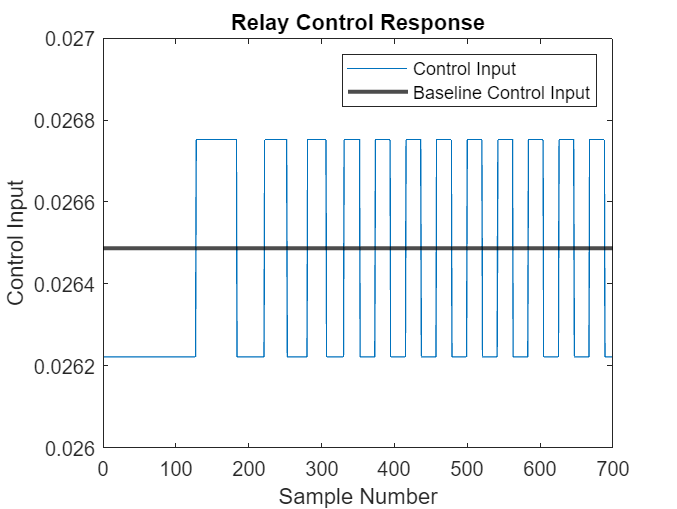


plot(1:n-1, u) % plot control input 
yline(baseline, 'k', 'LineWidth', 2) % plot baseline line
ylim([0.026 0.027])
title("Relay Control Response")
xlabel("Sample Number")
ylabel("Control Input") 
legend("Control Input", "Baseline Control Input")

2--Repeat with baseline at 99% of the Ball’s weight and same increment. Identify differences

with item 1.

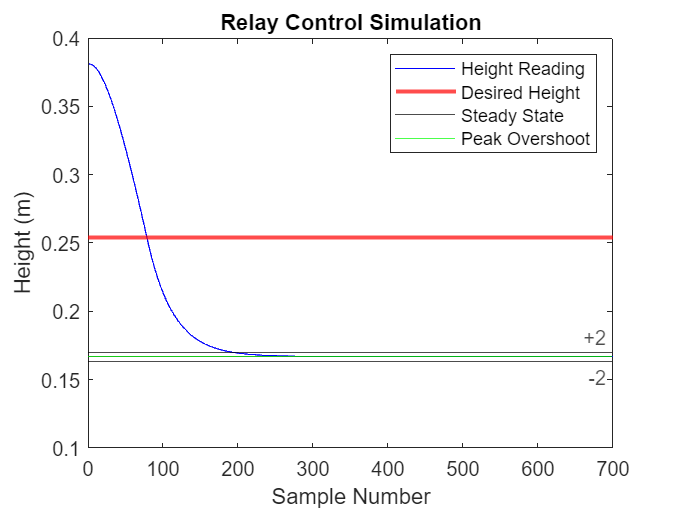

n = 700; % number of samples
x1 = zeros(1,n); % initialize velocity matrix
x2 = zeros(1,n); % initialize position matrix
x1(1) = 0; % start at rest
x2(1) = 0.381; % start at 0.381 m

desired_height = 0.254; 
baseline = 0.99* M * g; % baseline equal to 99% of weight
incremental = 0.01 * M * g; % incremental equal to 1% of weight
u = zeros(1,n-1); % initialize control input matrix

% loop through number of samples
for i = 1:n-1
    error = desired_height - x2(i); % calculate error
    
    % relay control logic
    if error > 0
        u(i) = baseline + incremental; % increase control input if below desired height
    else
        u(i) = baseline - incremental; % decrease control input if above desired height
    end

    x1(i+1) = x1(i) - g * T - (1/M) * 10 * B * x1(i) * T + (1/M) * u(i) * T; % update velocity matrix
    x2(i+1) = x2(i) + x1(i) * T; % update position matrix
end

plot(1:n, x2, 'b') % plot position
ylim([0.1 0.4])
yline(desired_height, "r",'LineWidth', 2) % plot desired height line
ss = mean(x2(400:end)); % calculate steady state error
yline(ss, 'k') % plot steady state
peak = min(x2); % calculate peak overshoot
yline(peak, 'g') % plot peak overshoot line
% calculate and plot + or - 2% steady state 
ss_max = ss * 1.02;
ss_min = ss * 0.98;
yline(ss_max, 'k', 'Label', '+2')
yline(ss_min, 'k', 'Label', '-2', 'LabelVerticalAlignment','bottom')
title("Relay Control Simulation")
xlabel("Sample Number")
ylabel("Height (m)") 
legend("Height Reading", "Desired Height", "Steady State", "Peak Overshoot")

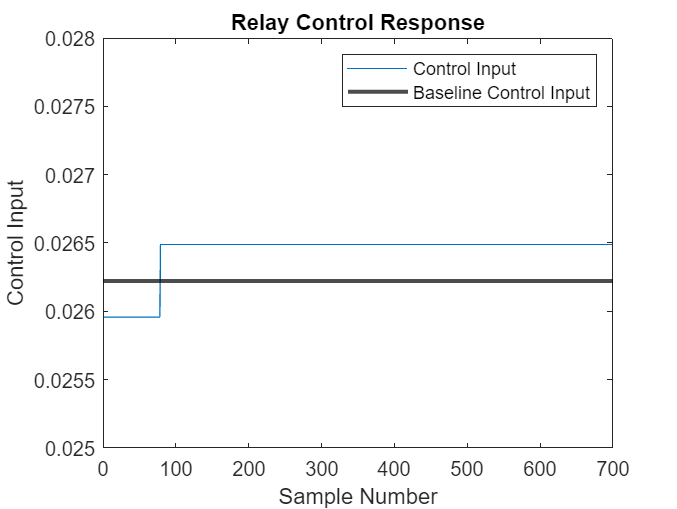


plot(1:n-1, u) % plot control input 
yline(baseline, 'k', 'LineWidth', 2) % plot baseline line
ylim([0.025 0.028])
title("Relay Control Response")
xlabel("Sample Number")
ylabel("Control Input") 
legend("Control Input", "Baseline Control Input")

P Controller: Same Initial Conditions (ICs).

1--Reset the baseline control to equal the weight of the Ball. Use a small value for Kp. Plot Ball

position v. time. Does P control perform as expected? Is there any steady-state error?

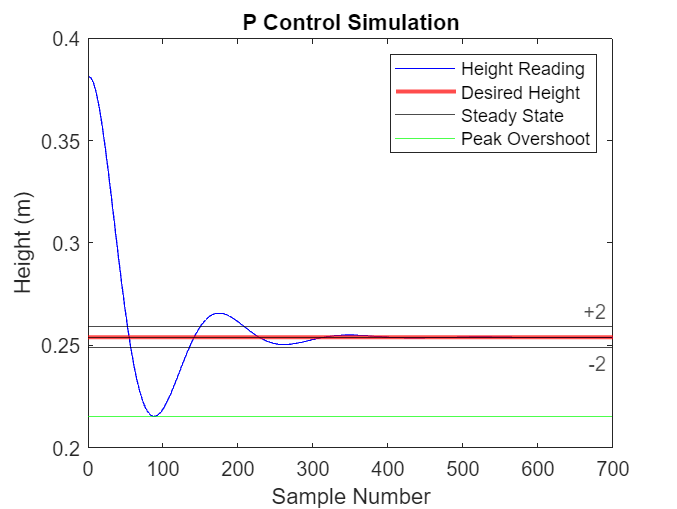

n = 700; % number of samples
x1 = zeros(1,n); % initialize velocity matrix
x2 = zeros(1,n); % initialize position matrix
x1(1) = 0; % start at rest
x2(1) = 0.381; % start at 0.381 m

Kp = 0.01; % proportional gain
desired_height = 0.254;
baseline = M * g; % baseline equal to weight
u = zeros(1,n-1); % initialize control input matrix

% loop through number of samples
for i = 1:n-1
    error = desired_height - x2(i); % calculate error

    u(i) = baseline + Kp * error; % proportional control

    x1(i+1) = x1(i) - g * T - (1/M) * 10 * B * x1(i) * T + (1/M) * u(i) * T; % update velocity matrix
    x2(i+1) = x2(i) + x1(i) * T; % update position matrix
end

plot(1:n, x2, 'b') % plot position
ylim([0.2 0.4])
yline(desired_height, "r",'LineWidth', 2) % plot desired height line
ss = mean(x2(500:end)); % calculate steady state error
yline(ss, 'k') % plot steady state
peak = min(x2); % calculate peak overshoot
yline(peak, 'g') % plot peak overshoot line
% calculate and plot + or - 2% steady state
ss_max = ss * 1.02;
ss_min = ss * 0.98;
yline(ss_max, 'k', 'Label', '+2')
yline(ss_min, 'k', 'Label', '-2', 'LabelVerticalAlignment','bottom')
title("P Control Simulation")
xlabel("Sample Number")
ylabel("Height (m)") 
legend("Height Reading", "Desired Height", "Steady State", "Peak Overshoot")

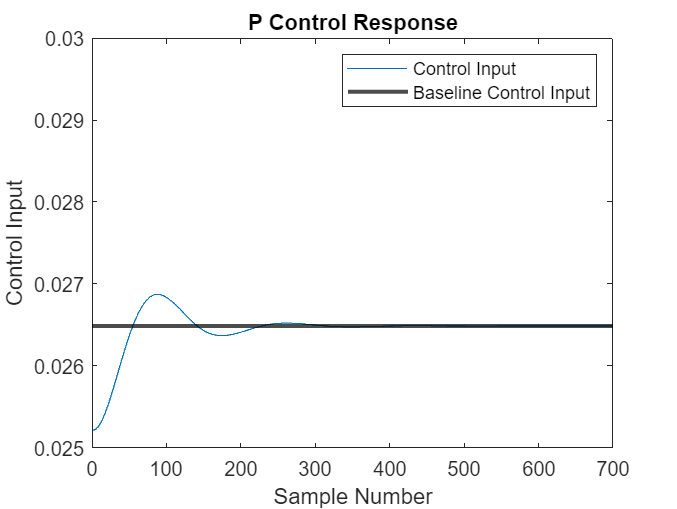


plot(1:n-1, u) % plot control input 
yline(baseline, 'k', 'LineWidth', 2) % plot baseline line
ylim([0.025 0.03])
title("P Control Response")
xlabel("Sample Number")
ylabel("Control Input") 
legend("Control Input", "Baseline Control Input")

2--Repeat with baseline at 90% of the Ball’s weight. Identify differences with item 1.

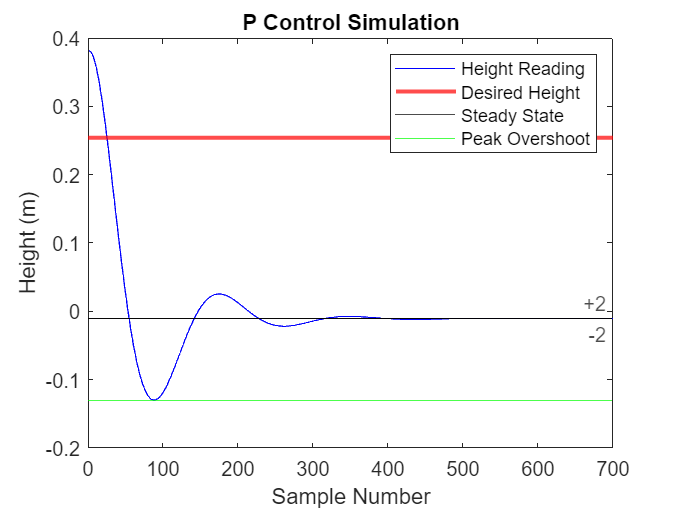

n = 700; % number of samples
x1 = zeros(1,n); % initialize velocity matrix
x2 = zeros(1,n); % initialize position matrix
x1(1) = 0; % start at rest
x2(1) = 0.381; % start at 0.381 m

Kp = 0.01; % proportional gain
desired_height = 0.254;
baseline = 0.9 * M * g; % baseline equal to 90% of weight
u = zeros(1,n-1); % initialize control input matrix

% loop through number of samples
for i = 1:n-1
    error = desired_height - x2(i); % calculate error

    u(i) = baseline + Kp * error; % proportional control

    x1(i+1) = x1(i) - g * T - (1/M) * 10 * B * x1(i) * T + (1/M) * u(i) * T; % update velocity matrix
    x2(i+1) = x2(i) + x1(i) * T; % update position matrix
end

plot(1:n, x2, 'b') % plot position
ylim([-0.2 0.4])
yline(desired_height, "r",'LineWidth', 2) % plot desired height line
ss = mean(x2(500:end)); % calculate steady state error
yline(ss, 'k') % plot steady state
peak = min(x2); % calculate peak overshoot
yline(peak, 'g') % plot peak overshoot line
% calculate and plot + or - 2% steady state
ss_max = ss * 1.02;
ss_min = ss * 0.98;
yline(ss_max, 'k', 'Label', '+2')
yline(ss_min, 'k', 'Label', '-2', 'LabelVerticalAlignment','bottom')
title("P Control Simulation")
xlabel("Sample Number")
ylabel("Height (m)") 
legend("Height Reading", "Desired Height", "Steady State", "Peak Overshoot")

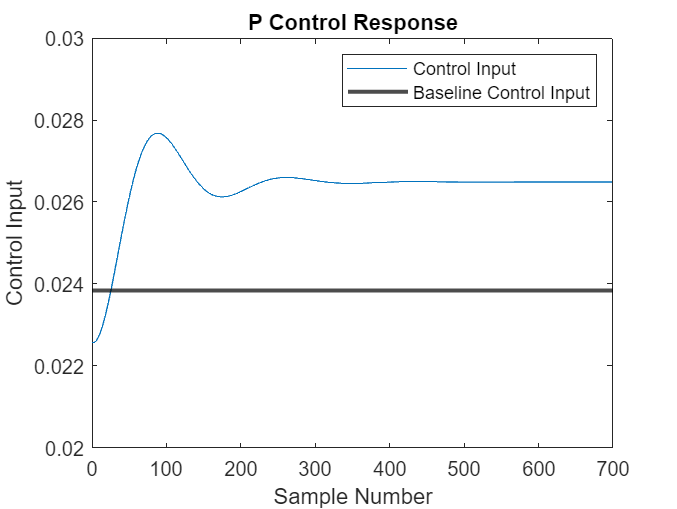


plot(1:n-1, u) % plot control input 
yline(baseline, 'k', 'LineWidth', 2) % plot baseline line
ylim([0.02 0.03])
title("P Control Response")
xlabel("Sample Number")
ylabel("Control Input") 
legend("Control Input", "Baseline Control Input")

Stretch Goal: Repeat with PI control.

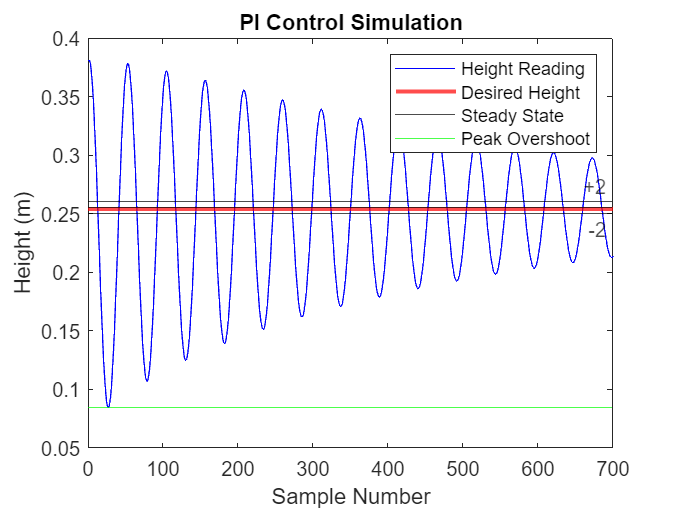

n = 700; % number of samples
x1 = zeros(1,n); % initialize velocity matrix
x2 = zeros(1,n); % initialize position matrix
x1(1) = 0; % start at rest
x2(1) = 0.381; % start at 0.381 m

Kp = 0.1; % proportional gain
Ki = 0.05; % integral grain
dVi = zeros(1,n); % integral incremnt
desired_height = 0.254;
baseline = 0.9 * M * g; % baseline equal to weight
u = zeros(1,n-1); % initialize control input matrix

% loop through number of samples
for i = 2:n
    error = desired_height - x2(i-1); % calculate error

    dVp = Kp * error; % increment iaw proportional control
    dVi(i) = dVi(i-1) + Ki * error * 0.02; % increment iaw integral control 
    u(i-1) = baseline + dVp + dVi(i); % proportional and integral control

    x1(i) = x1(i-1) - g * T - (1/M) * 10 * B * x1(i-1) * T + (1/M) * u(i-1) * T; % update velocity matrix
    x2(i) = x2(i-1) + x1(i-1) * T; % update position matrix
end

plot(1:n, x2, 'b') % plot position
%ylim([0.2 0.4])
yline(desired_height, "r",'LineWidth', 2) % plot desired height line
ss = mean(x2(600:end)); % calculate steady state error
yline(ss, 'k') % plot steady state
peak = min(x2); % calculate peak overshoot
yline(peak, 'g') % plot peak overshoot line
% calculate and plot + or - 2% steady state
ss_max = ss * 1.02;
ss_min = ss * 0.98;
yline(ss_max, 'k', 'Label', '+2')
yline(ss_min, 'k', 'Label', '-2', 'LabelVerticalAlignment','bottom')
title("PI Control Simulation")
xlabel("Sample Number")
ylabel("Height (m)") 
legend("Height Reading", "Desired Height", "Steady State", "Peak Overshoot")

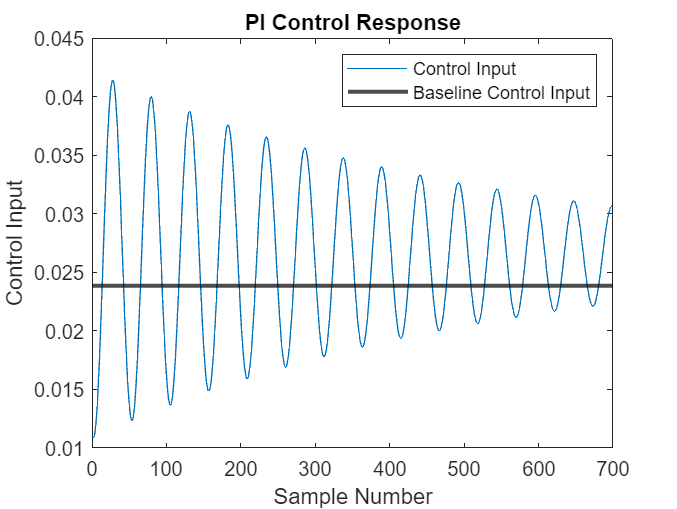


plot(1:n-1, u) % plot control input 
yline(baseline, 'k', 'LineWidth', 2) % plot baseline line
%ylim([0.025 0.03])
title("PI Control Response")
xlabel("Sample Number")
ylabel("Control Input") 
legend("Control Input", "Baseline Control Input")